clear
close all
clc
seed = 1234

seed = 1234

rng(seed)

FNT_SZ = 16;

%% Set the LPA parameters

% maximum degree of polynomial used for fitting
N = 3;
% parameter for the confidence intervals in the ICI rule
Gamma = 2;

% Set all the scale values
hmax = 51;
all_h = 1:hmax;

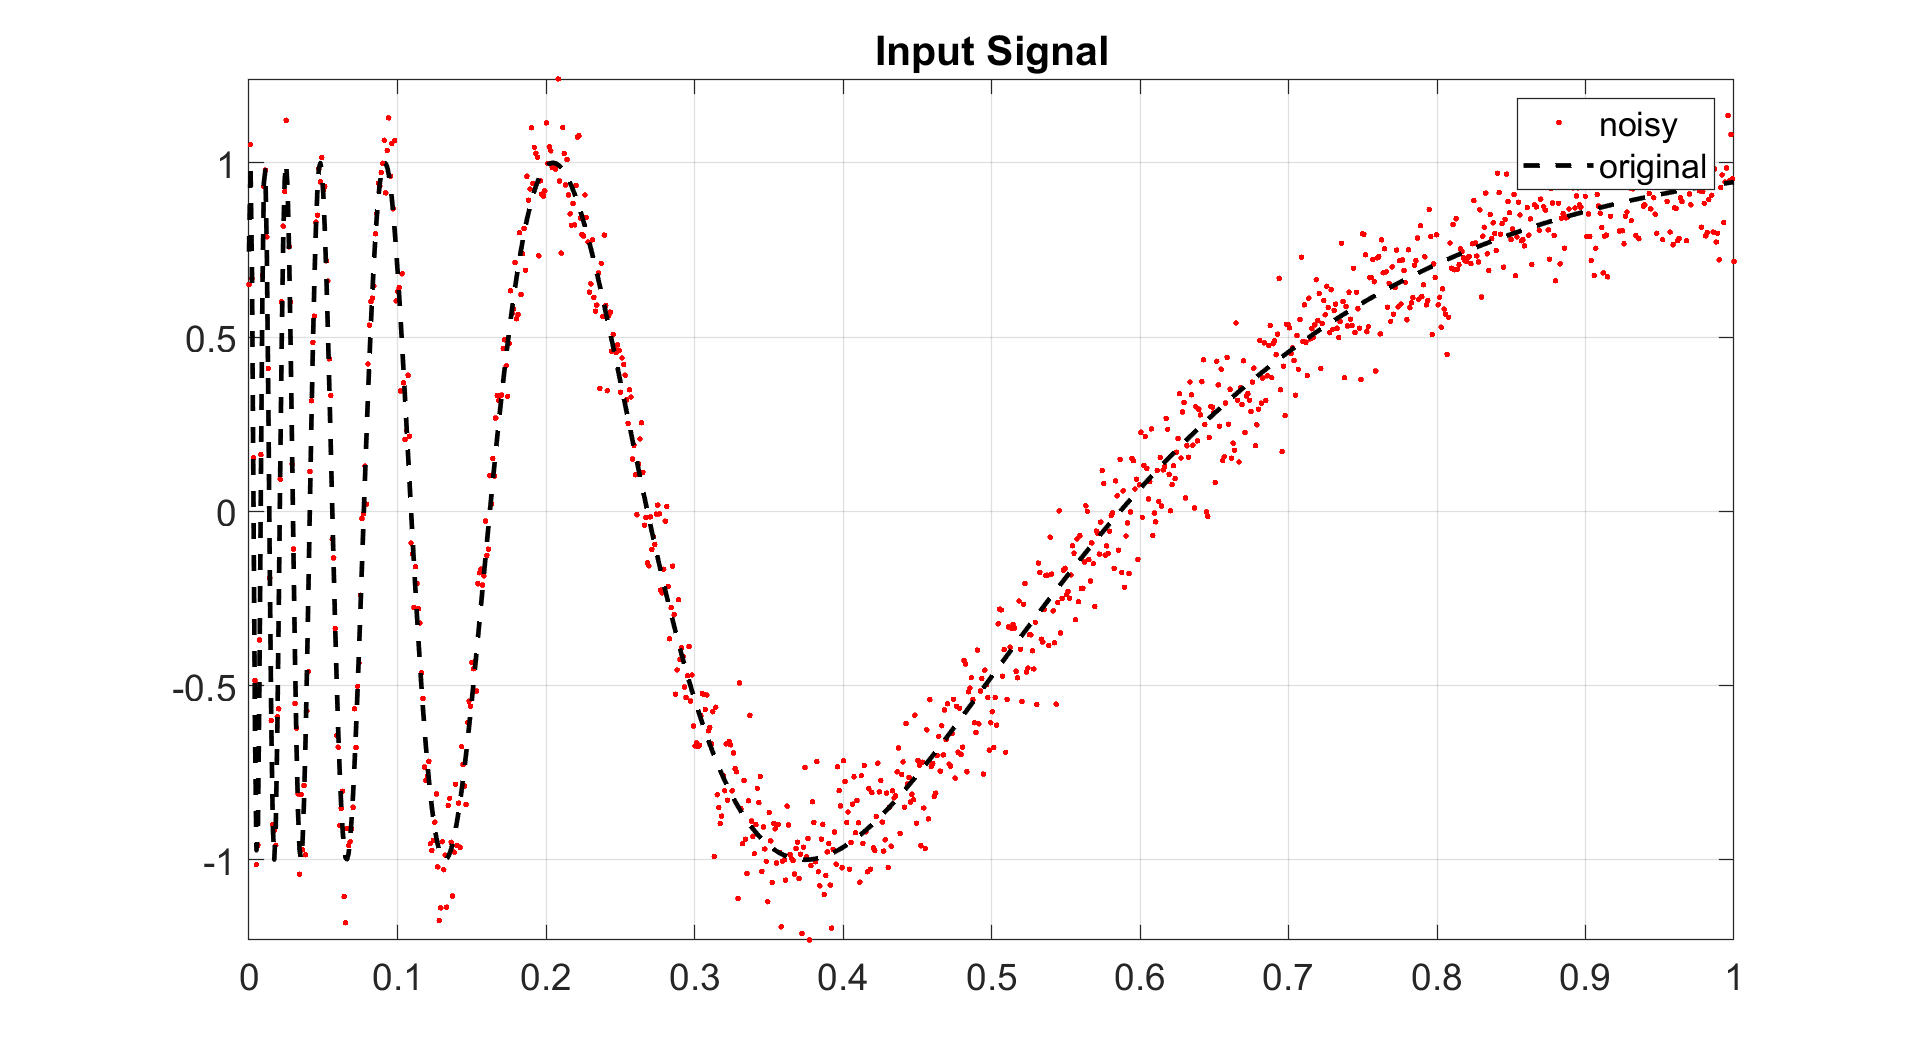


%% Generate Signal

% Generate the entire signal
LENGTH = 1000;
[y, ty] = get_synthetic_signal('sine', LENGTH);

% noise standard deviation
sigma = 0.1;

% noisy signal 
s = y + sigma*randn(size(y));

figure(2), 
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 2);
hold off
grid on
axis tight
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original');
title('Input Signal')
set(gcf, 'Position', [ 103 1 1574 867])

%% generate the LPA kernels for all the scale

all_g = cell(length(all_h),1);
for ii=1:length(all_h)
    h = all_h(ii);
    %h is defined as (number of nonzero elements +1)/2
    
    % define the weights for the scale h (symmetric, left or right)
    % centered kernel
    
    w = zeros(2*h-1, 1);
    HFS = floor(size(w,1) / 2);
    wc = w;
    wc(floor(HFS /2) + 1 : end - floor(HFS/2)) = 1;

    wl = w;
    wl(1 : HFS + 1) = 1;

    wr = w;
    wr(HFS + 1 : end) = 1;
    
    w = wr;
    
    % compute and store the kernel g
    g = compute_LPA_kernel(w, N, ty);
    all_g{ii} = g;
end

%% find the best scale for each sample using the LPA-ICI rule
% initialize the estimate for each scale
all_shat = zeros(size(all_h,2), LENGTH);

% initialize the vector containing the best scale for each sample
best_scale = zeros(1,LENGTH);

% initialize the lower and upper bound vectors
lower_bounds = -ones(1, LENGTH)*Inf;
upper_bounds = ones(1, LENGTH)*Inf;
% loop over all the scales
for ii=1:length(all_h)
    
    h = all_h(ii);
    g = all_g{ii};
    
    % compute the estimate for the scale h
    shat = conv(s, g, "same");
    
    % store the computed estimate
    all_shat(ii, :) = shat';
    
    % compute the lower and upper bound of the confidence interval for scale h
     lb = shat' - Gamma*sigma*norm(g, 2);
     ub = shat' + Gamma*sigma*norm(g, 2);

    % update the lower and upper bounds 
     lower_bounds = max(lower_bounds, lb);
     upper_bounds = min(upper_bounds, ub);
    
    % identify for which samples h is the best scale according to the
    % ICI rule and update the best_scale vector accordingly
    idx = find((upper_bounds < lower_bounds) .* (best_scale==0));
    if ~isempty(idx)
        best_scale(idx) = h-1;
    end
    
end
idx = find(best_scale ==0);
if ~isempty(idx)
   best_scale(idx) = h;
end

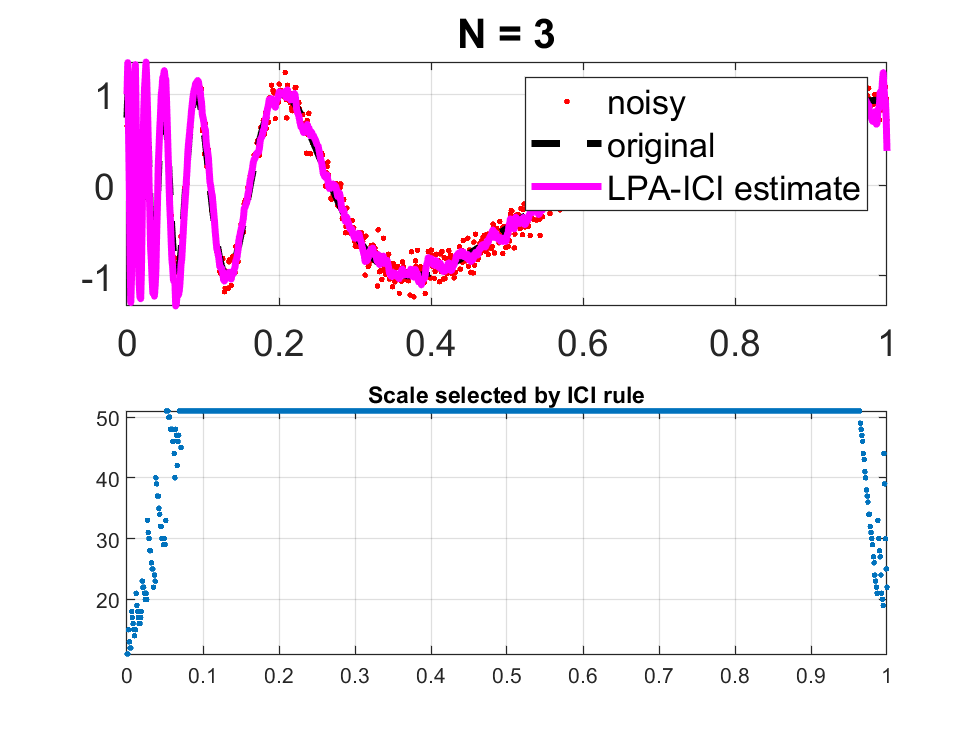

%% use the best scale for each sample to compute the final estimates
sfinal = zeros(LENGTH,1);
for n=1:LENGTH
    best_h = best_scale(n);
    sfinal(n) = all_shat(best_h, n);
end


figure(5), 
subplot(2, 1, 1)
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 3);
plot(ty, sfinal, 'm-','LineWidth', 3);
hold off
grid on
axis tight
title(['N = ', num2str(N)])
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original', 'LPA-ICI estimate');

subplot(2, 1, 2)
plot(ty, best_scale, '.')
title('Scale selected by ICI rule')
grid on
axis tight